#  Summary of days (hour) by trial mean

%clearvars -except kg kg2

## Good kg idx - single fish

clearvars -except kg kg2 rkg 
zx = 1;
xz = 1;

kg = rkg;

ReFs = 20; 
%detrending is an issue 


%4:4 LD
% left out trials: 116 (same as 141), 117 (same as 142)
ch1hourexp(zx).idx = [1 2 54 143 144 145];
    ch1hourexp(zx).hour = 4;
    
ch2hourexp(xz).idx = [55];% 142 143 145]; %[1 2 55] %145 may be weird
    ch2hourexp(xz).hour = 4;
%AMP RANGES - GAIN CHECK    
%kg(1).e(1)
    
    for k = 1:length(ch1hourexp(zx).idx)
        fourch1(k).day = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 1, ReFs, 3);
        lfourch1(k).day = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 1, ReFs, 4);

%         dark(zx).h(k).day = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 1, ReFs, 3);
%         light(zx).h(k).day = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 1, ReFs, 4);
    end

    for kk = 1:length(ch2hourexp(xz).idx)
        fourch2(kk).day = KatieRegfftDayDessembler(kg(ch2hourexp(xz).idx(kk)), 2, ReFs, 3);
        lfourch2(k).day = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 2, ReFs, 4);
    end

    dark(zx).h = [fourch1 fourch2];
    light(zx).h = [lfourch1 lfourch2];

%5:5 LD

    zx = zx + 1; %2
  %  xz = xz +1; %2

ch1hourexp(zx).idx = [18 19 58 59 135 137]; 
                     %136-not enough points-too spikey 
                     %k = 20  too spikey
    ch1hourexp(zx).hour = 5;
% ch2hourexp(xz).idx = [59 ]; %59 %96 %19 18
%     ch2hourexp(xz).hour = 5;


%     for k = 1:length(ch1hourexp(zx).idx)
%         dark(zx).h(k).trial = KatieRegfftDayTrialDessembler(kg(ch1hourexp(zx).idx(k)), 1, ReFs, 3);
%     end

    for k = 1:length(ch1hourexp(zx).idx)
        dark(zx).h(k).day = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 1, ReFs, 3);
        light(zx).h(k).day = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 1, ReFs, 4);
    end

%     for kk = 1:length(ch2hourexp(xz).idx)
%         fivech2(kk).trial = KatieRegfftDayTrialDessembler(kg(ch2hourexp(xz).idx(kk)), 2, ReFs, 3);
%     end

   % dark(zx).h = [fivech1 fivech2];
  

 %6:6 LD
 
    
    zx = zx + 1; %3;
    

ch1hourexp(zx).idx = [8, 158, 9, 155, 156, 157]; %9 %33 %99   DETRENDING IS A PROBLEM! - 8, 31 (8 different poweridx)
    ch1hourexp(zx).hour = 6;
ch2hourexp(xz).idx = [33 34]; %34 detrending problems
    ch2hourexp(xz).hour = 6;


     for k = 1:length(ch1hourexp(zx).idx)
        six1(k).day = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 1, ReFs, 3);
        lsix1(k).day = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 1, ReFs, 4);
     end
    
     for kk = 1:length(ch2hourexp(xz).idx)
        six2(kk).day = KatieRegfftDayDessembler(kg(ch2hourexp(xz).idx(kk)), 2, ReFs, 3);
        lsix2(kk).day = KatieRegfftDayDessembler(kg(ch2hourexp(xz).idx(kk)), 2, ReFs, 4);
     end

     dark(zx).h = [six1 six2];
     light(zx).h = [lsix1 lsix2];

 %8:8 LD  

    zx = zx + 1; %4;
    xz = xz +1; %3


ch1hourexp(zx).idx = [27 35 36 147 148 149 150 151]; %25 26 27 35 36
    ch1hourexp(zx).hour = 8;
ch2hourexp(xz).idx = [25, 26]; %DETRENDING!!! NEED IT
     ch2hourexp(xz).hour = 8;

%     for k = 1:length(ch1hourexp(zx).idx)
%         dark(zx).h(k).day = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 1, ReFs, 3);
%         light(zx).h(k).day = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 1, ReFs, 4);
%     end

     for k = 1:length(ch1hourexp(zx).idx)
        eit1(k).day = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 1, ReFs, 3);
        leit1(k).day = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 1, ReFs, 4);
     end
    
     for kk = 1:length(ch2hourexp(xz).idx)
        eit2(kk).day = KatieRegfftDayDessembler(kg(ch2hourexp(xz).idx(kk)), 2, ReFs, 3);
        leit2(kk).day = KatieRegfftDayDessembler(kg(ch2hourexp(xz).idx(kk)), 2, ReFs, 4);
     end

     dark(zx).h = [eit1 eit2];
     light(zx).h = [leit1 leit2];


    %zx = 5;
    zx = zx + 1;
    xz = xz +1;

%10:10 LD
ch1hourexp(zx).idx= [7 60 61 86 88 89]; %60 is a mountain %61 multi modal? %88-would be wider poweridx with detrending 89 again with detrending
        %amplitude for 6 is super tiny compared to the rest of the data
    ch1hourexp(zx).hour = 10;

ch2hourexp(xz).idx = [87]; %61 outlier fish %60, 95
  ch2hourexp(xz).hour = 10;

%     for k = 1:length(ch1hourexp(zx).idx)
%         dark(zx).h(k).day  = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 2, ReFs, 3);
%         light(zx).h(k).day  = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 2, ReFs, 4);
%     end

    for k = 1:length(ch1hourexp(zx).idx)
        dark(zx).h(k).day = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 1, ReFs, 3);
    end

    for kk = 1:length(ch2hourexp(xz).idx)
        tench2(kk).day = KatieRegfftDayDessembler(kg(ch2hourexp(xz).idx(kk)), 2, ReFs, 3);
    end
% 
     dark(zx).h = [tench1 tench2];



    %zx = 6;
    zx = zx + 1;
    xz = xz +1;

%12:12 LD
ch1hourexp(zx).idx = [12 13 14 15 16 21 84];  
            %k = 17 good but time base issue - starts after lighttimes 
            %21 seriously needs detrending 
            %13 would be better with detrending
            %23 left out...
            %85 left out - not bad, just very squiggly
           
    ch1hourexp(zx).hour = 12;
ch2hourexp(xz).idx = [24]; 
    ch2hourexp(xz).hour = 12;

    for k = 1:length(ch1hourexp(zx).idx)
        twelvech1(k).day = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 1, ReFs, 3);
        ltwelvech1(k).day = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 1, ReFs, 4);
    end

    for kk = 1:length(ch2hourexp(xz).idx)
        twelvech2(kk).day = KatieRegfftDayDessembler(kg(ch2hourexp(xz).idx(kk)), 2, ReFs, 3);
        ltwelvech2(kk).day = KatieRegfftDayDessembler(kg(ch2hourexp(xz).idx(kk)), 2, ReFs, 4);
    end

    dark(zx).h = [twelvech1 twelvech2];
    light(zx).h = [ltwelvech1 ltwelvech2];


    %zx = 7;
    zx = zx + 1;
    xz = xz +1;

%13:13 LD
ch1hourexp(zx).idx = [28 30 31 129 130 132]; 
                    %31 is 28 trimmed to second half (32 is full data set) 
                        %poweridx would be longer with detrending
                    %29 left out - too spikey
                    %30 would be better with detrending
                    %131 left out - single squiggly day
    ch1hourexp(zx).hour = 13;

    for k = 1:length(ch1hourexp(zx).idx)
        dark(zx).h(k).day = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 1, ReFs, 3);
        light(zx).h(k).day = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 1, ReFs, 4);
    end

% ch2hourexp(xz).idx = []; %29 %133 %31 %129 %[30  31]
%      ch2hourexp(xz).hour = 13;

%     for k = 1:length(ch1hourexp(zx).idx)
%         teench1(k).day = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 1, ReFs, 3);
%         lteench1(k).day = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 1, ReFs, 4);
%     end
% 
%     for kk = 1:length(ch2hourexp(xz).idx)
%         teench2(kk).day = KatieRegfftDayDessembler(kg(ch2hourexp(xz).idx(kk)), 2, ReFs, 3);
%         lteench2(kk).day = KatieRegfftDayDessembler(kg(ch2hourexp(xz).idx(kk)), 2, ReFs, 4);
%     end
% 
%     dark(zx).h = [teench1 teench2];
%     light(zx).h = [lteench1 lteench2];


    %zx = 8;
    zx = zx + 1;
    %xz = xz + 1;


%20:20 LD
ch1hourexp(zx).idx = [37 38 40 90 92 93]; %39
                    %38 - a bit sqiggly
                    %39 may be recoverable with detrending 
                    %
    ch1hourexp(zx).hour = 20;
ch2hourexp(xz).idx = [91]; %39
    ch2hourexp(xz).hour = 20;

%     for k = 1:length(ch1hourexp(zx).idx)
%         dark(zx).h(k).day = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 1, ReFs, 3);
%       
%     end
% 
%     for k = 1:length(ch1hourexp(zx).idx)-1
%         light(zx).h(k).day = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 1, ReFs, 4);
%     end


    for k = 1:length(ch1hourexp(zx).idx)
        teench1(k).day = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 1, ReFs, 3);
        lteench1(k).day = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 1, ReFs, 4);
    end

    for kk = 1:length(ch2hourexp(xz).idx)
        teench2(kk).day = KatieRegfftDayDessembler(kg(ch2hourexp(xz).idx(kk)), 2, ReFs, 3);
        lteench2(kk).day = KatieRegfftDayDessembler(kg(ch2hourexp(xz).idx(kk)), 2, ReFs, 4);
    end

    dark(zx).h = [teench1 teench2];
    light(zx).h = [lteench1 lteench2];


    %zx = 9;
    zx = zx + 1;
    xz = xz +1;

%24:24 LD
ch1hourexp(zx).idx = [10 11 56 76 77 78 79]; 
                     %10 time problem or poweridx would be longer
                     %57 - left out.. not bad just very spikey - maybe add back later   
    ch1hourexp(zx).hour = 24;


    for k = 1:length(ch1hourexp(zx).idx)
        dark(zx).h(k).day = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 1, ReFs, 3);
        light(zx).h(k).day = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 1, ReFs, 4);
    end

% ch2hourexp(xz).idx = [57 120]; 
%     ch2hourexp(xz).hour = 24;

%     for k = 1:length(ch1hourexp(zx).idx)
%         twofour1(k).day = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 1, ReFs, 3);
%         ltwofour1(k).day = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 1, ReFs, 4);
%     end
% 
%     for kk = 1:length(ch2hourexp(xz).idx)
%         twofour2(kk).day = KatieRegfftDayDessembler(kg(ch2hourexp(xz).idx(kk)), 2, ReFs, 3);
%         ltwofour2(kk).day = KatieRegfftDayDessembler(kg(ch2hourexp(xz).idx(kk)), 2, ReFs, 4);
%     end
% 
%     dark(zx).h = [twofour1 twofour2];
%     light(zx).h = [ltwofour1 ltwofour2];
    
    %zx = 10;
    zx = zx + 1;
    %xz = xz +1;

%48:48 LD
ch1hourexp(zx).idx = [ 5 44 80 81 82 106];%[3 4 5 44 80 81 82 106]
                    %45 shit data - noise issues maybe
                    %46 left out for now - bit messy not too bad
                    %83 single day - kinda messy but not too bad
                    %102 single day (starts with light)
                    %107 messy
    ch1hourexp(zx).hour = 48;
%ch2hourexp(xz).idx = [107]; %104]; %44 45 %104 better for ch2 %[3 4 5 44 80 81 82 107 106 104]
    %ch2hourexp(xz).hour = 48;

%     for k = 1:length(ch1hourexp(zx).idx)
%         foureight1(k).trial = KatiefftDayTrialDessembler(kg(ch1hourexp(zx).idx(k)), 1, ReFs, 3);
%     end
% 
%     for kk = 1:length(ch2hourexp(xz).idx)
%         foureight2(kk).trial = KatiefftDayTrialDessembler(kg(ch2hourexp(xz).idx(kk)), 2, ReFs, 3);
%     end 
% dark(zx).h = [foureight1 foureight2];


    for k = 1:length(ch1hourexp(zx).idx)
        dark(zx).h(k).day = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 1, ReFs, 3);
        light(zx).h(k).day = KatieRegfftDayDessembler(kg(ch1hourexp(zx).idx(k)), 1, ReFs, 4);
    end
   

## Colors

%define colors
%divide each color code by 255 to convert to matlab RGB format

%Blue sky
BlueSky = [106/255, 90/255, 205/255];

%
PaleVioletRed = [255/255, 105/255, 180/255];

%Bluish green
Bluishgreen = [103/255, 189/255, 170/255];

%Moderate Red
Crimson = [220/255, 20/255, 60/255];

%Orange yellow
Orangeyellow = [224/255, 163/255, 46/255];

%Yellow Green
Yellowgreen = [157/255, 188/255, 64/255];

%Cyan
Cyan = [8/255, 133/255, 161/255];

%Dark skin (brown)
Brown = [115/255, 82/255, 68/255];

%coral
Coral = [255/255, 127/255, 80/255];

%Foliage (dark green)
Foliage = [87/255, 108/255, 67/255];

%Magenta
Magenta = [187/255, 86/255, 149/255];

Black = [0/255, 0/255, 0/255];


colorsforplots = [Coral; Crimson; Foliage; PaleVioletRed; Bluishgreen; Black; Yellowgreen; Orangeyellow; Magenta; Cyan; Brown];



Resample rate for cubic spline estimate. Units in samples per hour

ReFs = 60;

# Dark to light day summaries

light = 3;

## Full hour range

### time base normalized to pi


%calculate the mean of the means for each hour
    for k = 1:length(dark)
        
     [dark(k).hourtim, dark(k).meanoftrialmeans, dark(k).expavgrange,dark(k).fish, dark(k).ld] = k_fftdaymovabovemeans(dark(k).h);
    end

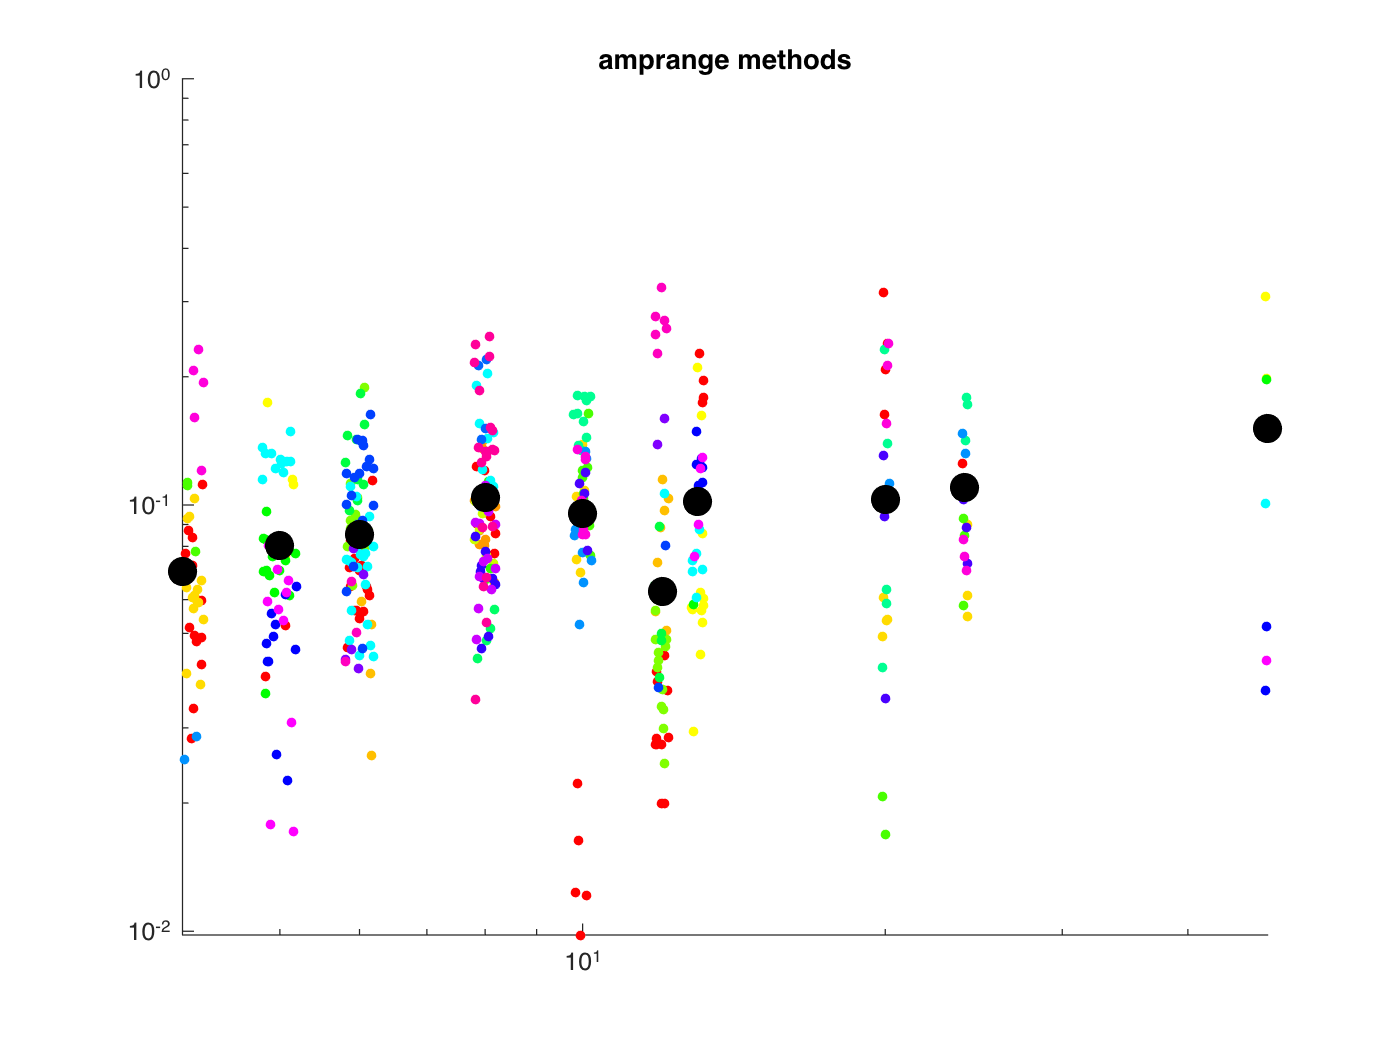

figure(89); clf; title('amprange methods'); hold on;

    for j = 1:length(dark)

        ld(j,:) = dark(j).ld;
       
        for kk = 1:length([dark(j).fish])
            clrbyfish = hsv(length(dark(j).fish));
            for jj = 1:length(dark(j).fish(kk).amprange)
            %plot(ld(j,:), dark(j).fish(kk).amprange(jj), '.', 'MarkerSize', 8);
            scatter(ld(j,:), dark(j).fish(kk).amprange(jj), 15, clrbyfish(kk,:),'filled','jitter', 'on', 'jitterAmount', 0.2);
            end
        end
        plot(ld(j,:), dark(j).expavgrange, 'k.', 'MarkerSize', 35);

    end
    set(gca,'xscale', 'log', 'yscale', 'log');

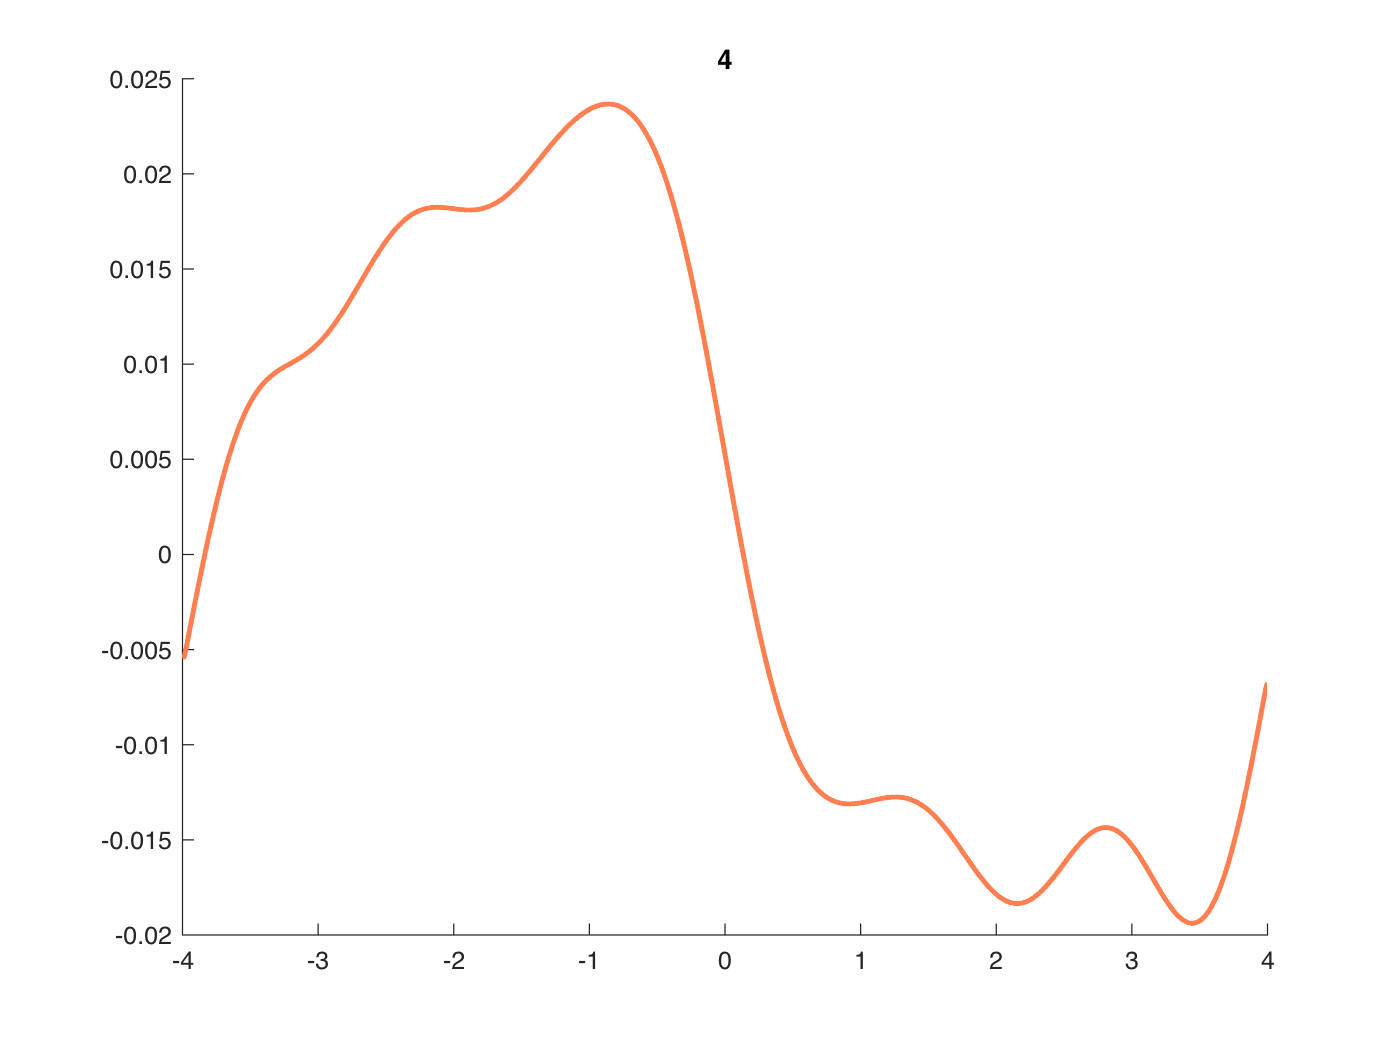

Unrecognized field name "expavgmin".

for j = 1:length(dark)
    ld(j,:) = dark(j).ld;
    figure(j); clf; title(num2str(ld(j))); hold on;
        plot(dark(j).hourtim - ld(j), dark(j).meanoftrialmeans,'LineWidth', 2,'Color', colorsforplots(j,:)');
        plot([0,0], ylim,'k-');
end


clear ld; 
clear p;
%plot
figure(317); clf; title('FFT Dark to Light'); hold on; 
    set(gca,'XTick',-2*pi:pi:2*pi)
    ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};


clear p;
% clrs = hsv(length(dark));
% %colororder(clrs);
% kk = randperm(length(dark));
% clrs = clrs(kk,:);

    for j = 1:length(dark)
      
        ld(j,:) = dark(j).ld;
        crosshour = (2*pi) / (2 * dark(j).ld);
        p(j) = plot((dark(j).hourtim .* crosshour)-pi, dark(j).meanoftrialmeans, 'LineWidth', 2,'Color', colorsforplots(j,:)');
        legend(p, num2str(ld)); 
        legend('AutoUpdate', 'off');
        
       
    end

    plot([0,0], ylim, 'k-', 'LineWidth', 2);


### Original time base centered around zero

clear p;
%plot
figure(318); clf; title('FFT Dark to Light'); hold on; 
    

    for j = 1:length(dark)
      
        ld(j,:) = dark(j).ld;
        p(j) = plot(dark(j).hourtim - ld(j), dark(j).meanoftrialmeans, 'LineWidth', 2,'Color', colorsforplots(j,:)');
        legend(p, num2str(ld)); 
        legend('AutoUpdate', 'off');
        
       
    end

    plot([0,0], ylim, 'k-', 'LineWidth', 2);

#### Dark to light, summary split

12:12 in black

shorter trials

%plot
figure(224); clf; title('FFT Dark to Light shorter trials'); hold on; 
    set(gca,'XTick',-2*pi:pi:2*pi)
    ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};

dark1under10 = 5;
clear p;
clrs = hsv(dark1under10);


    for j = 1:5

        ld(j,:) = dark(j).ld;
        crosshour = (2*pi) / (2 * dark(j).ld);
        p(j) = plot((dark(j).hourtim .* crosshour)-pi, dark(j).meanoftrialmeans, 'LineWidth', 2,'Color', clrs(j,:));
        legend(p, num2str(ld)); 
        legend('AutoUpdate', 'off');
        
    end

    j = 6;
    crosshour = (2*pi) / (2 * dark(j).ld);
    p(j) = plot((dark(j).hourtim .* crosshour)-pi, dark(j).meanoftrialmeans, 'LineWidth', 2, 'Color', 'k');
   
    plot([0,0], ylim, 'k-');

figure(334); clf; title('FFT Dark to Light shorter trials'); hold on; 
    

dark1under10 = 5;
clear p;
clrs = hsv(dark1under10);
%colororder(clrs);



    for j = 1:5

        ld(j,:) = dark(j).ld;
       
        p(j) = plot(dark(j).hourtim -ld(j,:), dark(j).meanoftrialmeans, 'LineWidth', 2,'Color', clrs(j,:));
        
    end

    j = 6;
   
    p(j) = plot(dark(j).hourtim -ld(j,:), dark(j).meanoftrialmeans, 'LineWidth', 2, 'Color', 'k');
   legend(p, num2str(ld)); 
        legend('AutoUpdate', 'off');
        
    plot([0,0], ylim, 'k-');
        

Longer trials

%plot

figure(225); clf; title('FFT Dark to Light Longer trials'); hold on; 
   set(gca,'XTick',-2*pi:pi:2*pi)
    ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};

dark1over10 = 4;
clear p;
clear j;
clrs = hsv(dark1over10);
%colororder(clrs);
% kk = randperm(dark1over10);
% clrs = clrs(kk,:);

    for j = 7:10



        ld((j-6),:) = dark(j).ld;
         crosshour = (2*pi) / (2 * dark(j).ld);
        p(j-6) = plot((dark(j).hourtim .* crosshour)-pi, dark(j).meanoftrialmeans, 'LineWidth', 2,'Color', clrs((j-6),:));
        legend(p, num2str(ld)); 
        legend('AutoUpdate', 'off');
        
    end

    j = 6;
    crosshour = (2*pi) / (2 * dark(j).ld);
    p(j) = plot((dark(j).hourtim .* crosshour)-pi, dark(j).meanoftrialmeans, 'LineWidth', 2, 'Color', 'k');
   
    plot([0,0], ylim, 'k-');
    

%plot

figure(225); clf; title('FFT Dark to Light Longer trials'); hold on; 
   
dark1over10 = 4;
clear p;
clear j;
clrs = hsv(dark1over10);
%colororder(clrs);
% kk = randperm(dark1over10);
% clrs = clrs(kk,:);

    for j = 7:10



        ld((j-6),:) = dark(j).ld;
        
        p(j-6) = plot(dark(j).hourtim - ld(j,:), dark(j).meanoftrialmeans, 'LineWidth', 2,'Color', clrs((j-6),:));
        legend(p, num2str(ld)); 
        legend('AutoUpdate', 'off');
        
    end

    j = 6;
    
    p(j) = plot(dark(j).hourtim -ld(j,:), dark(j).meanoftrialmeans, 'LineWidth', 2, 'Color', 'k');
   
    plot([0,0], ylim, 'k-');


%    
%      for k = 1:length(dark)
% 
%          db(k) = k_dB(dark(k));
%         
%      end
% 
% figure(789); clf; hold on;
%      for k = 1:length(db)
%          
% %          plot(db(k).ld, db(k).dbhourmaxmean, '.', 'MarkerSize', 10, 'Color', 'b'); %xlim([0,50]);
% %             plot([db(k).ld, db(k).ld], [db(k).dbhourmaxmeanmin, db(k).dbhourmaxmeanmax], '-', 'Color','b');
%        plot(log(db(k).ld), db(k).dbhourdaymean, '.', 'MarkerSize', 10, 'Color', 'r'); %xlim([0,50]);
%             plot(log([db(k).ld, db(k).ld]), [db(k).daymeanmin, db(k).daymeanmax], '-', 'Color','r');
% %         p(j) = plot((dark(j).hourtim .* crosshour)-pi, dark(j).meanoftrialmeans, 'LineWidth', 2,'Color', colorsforplots(j,:)');
% %         legend(p, num2str(ld)); 
% %         legend('AutoUpdate', 'off');
%         
%        
%    end

    %plot([0,0], ylim, 'k-', 'LineWidth', 2);

% %calculate the mean of the means for each hour
%     for k = 1:length(light)
%         
%      [light(k).hourtim, light(k).meanoftrialmeans, light(k).hourampmax, light(k).ld] = k_fftdaymovabovemeans(light(k).h);
%     end
% 
% 
% clear ld; 
% clear p;
% %plot
% figure(317); clf; title('FFT Dark to Light'); hold on; 
%     set(gca,'XTick',-2*pi:pi:2*pi)
%     ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};
% 
% 
% clear p;
% % clrs = hsv(length(dark));
% % %colororder(clrs);
% % kk = randperm(length(dark));
% % clrs = clrs(kk,:);
% 
%     for j = 1:length(light)
%       
%         ld(j,:) = light(j).ld;
%         crosshour = (2*pi) / (2 * dark(j).ld);
%         p(j) = plot((light(j).hourtim .* crosshour)-pi, light(j).meanoftrialmeans, 'LineWidth', 2,'Color', colorsforplots(j,:)');
%         legend(p, num2str(ld)); 
%         legend('AutoUpdate', 'off');
%         
%        
%     end
% 
%     plot([0,0], ylim, 'k-', 'LineWidth', 2);

% clear p;
% %plot
% figure(318); clf; title('FFT Dark to Light'); hold on; 
%     
% 
%     for j = 1:length(light)
%       
%         ld(j,:) = light(j).ld;
%         p(j) = plot(light(j).hourtim - ld(j), light(j).meanoftrialmeans, 'LineWidth', 2,'Color', colorsforplots(j,:)');
%         legend(p, num2str(ld)); 
%         legend('AutoUpdate', 'off');
%         
%        
%     end
% 
%     plot([0,0], ylim, 'k-', 'LineWidth', 2);

#### Dark to light, summary split

12:12 in black

shorter trials

% %plot
% figure(324); clf; title('FFT Light to Dark Shorter trials'); hold on; 
%     set(gca,'XTick',-2*pi:pi:2*pi)
%     ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};
% 
% dark1under10 = 5;
% clear p;
% clrs = hsv(dark1under10);
% %colororder(clrs);
% 
% 
% 
%     for j = 1:5
% 
%         ld(j,:) = light(j).ld;
%         crosshour = (2*pi) / (2 * light(j).ld);
%         p(j) = plot((light(j).hourtim .* crosshour)-pi, light(j).meanoftrialmeans, 'LineWidth', 2,'Color', clrs(j,:));
%         
%     end
% 
%     j = 6;
%     crosshour = (2*pi) / (2 * light(j).ld);
%     p(j) = plot((light(j).hourtim .* crosshour)-pi, light(j).meanoftrialmeans, 'LineWidth', 2, 'Color', 'k');
%     legend(p, num2str(ld)); 
%     legend('AutoUpdate', 'off');
%         
%     plot([0,0], ylim, 'k-');
% 

Longer trials

%     %plot
% figure(325); clf; title('FFT Light to Dark Longer trials'); hold on; 
%     set(gca,'XTick',-2*pi:pi:2*pi)
%     ax.XTickLabel = {'-2\pi','-\pi','0','\pi','2\pi'};
% 
% dark1over10 = 4;
% clear p;
% clear j;
% clrs = hsv(dark1over10);
% %colororder(clrs);
% % kk = randperm(dark1over10);
% % clrs = clrs(kk,:);
% 
%     for j = 7:10
% 
%         ld((j-6),:) = light(j).ld;
%         crosshour = (2*pi) / (2 * light(j).ld);
%         p(j-6) = plot((dark(j).hourtim .* crosshour)-pi, dark(j).meanoftrialmeans, 'LineWidth', 2,'Color', clrs((j-6),:));
%         
%         
%     end
% 
%     j = 6;
%     crosshour = (2*pi) / (2 * dark(j).ld);
%     p(j) = plot((dark(j).hourtim .* crosshour)-pi, dark(j).meanoftrialmeans, 'LineWidth', 2, 'Color', 'k');
%     legend(p, num2str(ld)); 
%         legend('AutoUpdate', 'off');
%     plot([0,0], ylim, 'k-');

% %  plot([0 0], ylim, 'k-');